cd('/Volumes/PcSSDA/1629/20220331_1629_SW_004')
ExperimentName='20220331_1629_SW_004'; % Give a specific name to this experiment or this analysis
FirstAcq=10; % What's the acquisition number of the first offical recording
number_of_acq = 24; % How many chunks of recordings are there?
Dark_hours=[10 11 12 13 14 15 16 17 18 19 20 21 22]

Dark_hours =     10    11    12    13    14    15    16    17    18    19    20    21    22


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time
rawdat_dir = pwd;
fileprefix=ExperimentName;% '20220323_1629_SW_003';
filepostfix='20220403';
frequency=1;
constant=FirstAcq-1;
mouse='1629';

EEGfile = 'extracted_data/downsampEEG_Acq11.npy'

scoring_python = 'extracted_data/StatesAcq11_hr0.npy'

file = '/Volumes/PcSSDA/1629/20220331_1629_SW_004/AD0_11.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/1629/20220331_1629_SW_004/AD2_11.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/1629/20220331_1629_SW_004/AD3_11.mat'

Loading wave object file ...


FLiPfile = '20220331_1629_SW_004_analysis_2h_20220403.mat'

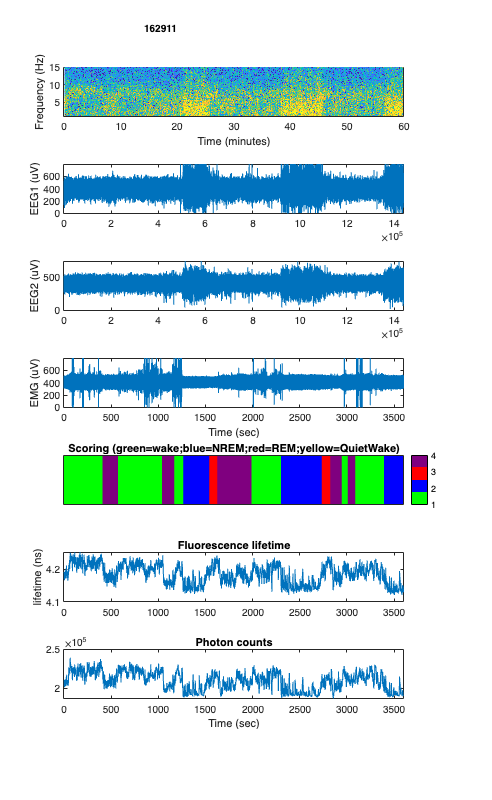


for acqn=11:11
    PlotEEGEMGFLiP(rawdat_dir, mouse, fileprefix, filepostfix, acqn, frequency, constant);
end


acqn=11;

EEGfile=['extracted_data/downsampEEG_Acq',num2str(acqn),'.npy']

EEGfile = 'extracted_data/downsampEEG_Acq11.npy'

EEGdata=readNPY(EEGfile);
Fs = 200; % 
tWindow = 10; % The window must be long enough to get 64ms of the signal
NWindow = Fs*tWindow; % Number of elements the window must have
window = hamming(NWindow); % Window used in the spectrogram
NFFT = NWindow;
NOverlap = NWindow*0.99; % We want a 99% overlap, 

% save ScoringData
% Get your ScoringData this way
% data=readNPY('StatesAcq2_hr0_mod.npy'); data2=readNPY('StatesAcq2_hr1_mod.npy');
% ScoringData=[data', data2'];
scoring_python=['extracted_data/StatesAcq',num2str(acqn),'_hr0.npy']

scoring_python = 'extracted_data/StatesAcq11_hr0.npy'

ScoringData=readNPY(scoring_python);
ScoringData=ScoringData'; % Pingchuan changed, based on the way we name the npy sleep scoring file. 11.19.2021.

ScaledEEGEMG=cell(3,1);
channels = [0 2 3]; %if EEG/EMG channels are 0, 2 and 3
for i=1:3
    file=sprintf(strcat(rawdat_dir,'/AD%d_%d.mat'),channels(i),acqn)
    load(file);
    eval(['ScaledEEGEMG{', int2str(i), ',1}=AD', int2str(channels(i)), '_', int2str(acqn), '.data/5000*10^6;']); %What is a more elegant way to access the data?
end

file = '/Volumes/PcSSDA/1629/20220331_1629_SW_004/AD0_11.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/1629/20220331_1629_SW_004/AD2_11.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/1629/20220331_1629_SW_004/AD3_11.mat'

Loading wave object file ...



% load FLiP data
% FLiPfile=sprintf('%s_acqn%d_Analysis.mat',fileprefix,acqn);
FLiPfile=[fileprefix,'_analysis_',num2str(acqn-constant),'h_',filepostfix,'.mat'] % Pingchuan changed, based on the way I name the FLiP analysis files.

FLiPfile = '20220331_1629_SW_004_analysis_2h_20220403.mat'

load(FLiPfile);
TimeRange=max(time); %time range to plot, in seconds, based on FLiP data. We need to specify it because ephys data sometimes exceeded the duration of FliP data.


figure1 = figure;
figure1.Position=[10 10 800 1000];

subplot1 = subplot(5,1,1,'Parent',figure1);
hold(subplot1,'on');
spectrogram(EEGdata, window, NOverlap, NFFT, Fs,'yaxis');
ylim([1,15])
% xlim([25 40])
caxis([-40 -10])
colorbar('off')
box(subplot1,'off');
hold(subplot1,'off');
axis(subplot1,'off')

subplot2 = subplot(5,1,2,'Parent',figure1);
hold(subplot2,'on');

% Create plot
EEGtime=1/400:1/400:3600;
plot(EEGtime, ScaledEEGEMG{3,1},'Color', 'k','Parent',subplot2);
xlim(subplot2,[0 3600]);
% ylim(subplot3,[0 800])

% Create ylabel
ylabel('EMG (uV)');
xlabel('Time (sec)')

box(subplot2,'off');
axis(subplot2,'off');
hold(subplot2,'off');


subplot3 = subplot(5,1,3,'Parent',figure1);

% Create heatmap
ScoringData=ScoringData([1:TimeRange/4]);
ScoringHeatMap=heatmap(figure1,ScoringData,'Colormap',[1 1 1;0 0.5 1;1 0 1;0.5 1 1],...
    'GridVisible','off',...
    'FontColor',[0 0 0],...
    'ColorLimits',[1 4],...
    'Title','Scoring (green=wake;blue=NREM;red=REM;yellow=QuietWake)');
ScoringHeatMap.YDisplayLabels=repmat(' ', 1, 1);
ScoringHeatMap.XDisplayLabels=repmat(' ', length(ScoringData), 1);
ScoringHeatMap.ColorbarVisible = 'off'

ScoringHeatMap =   HeatmapChart (Scoring (green=wake;blue=NREM;red=REM;yellow=QuietWake)) with properties:

        XData: {900×1 cell}
        YData: {'1'}
    ColorData: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 … ]

  Show all properties


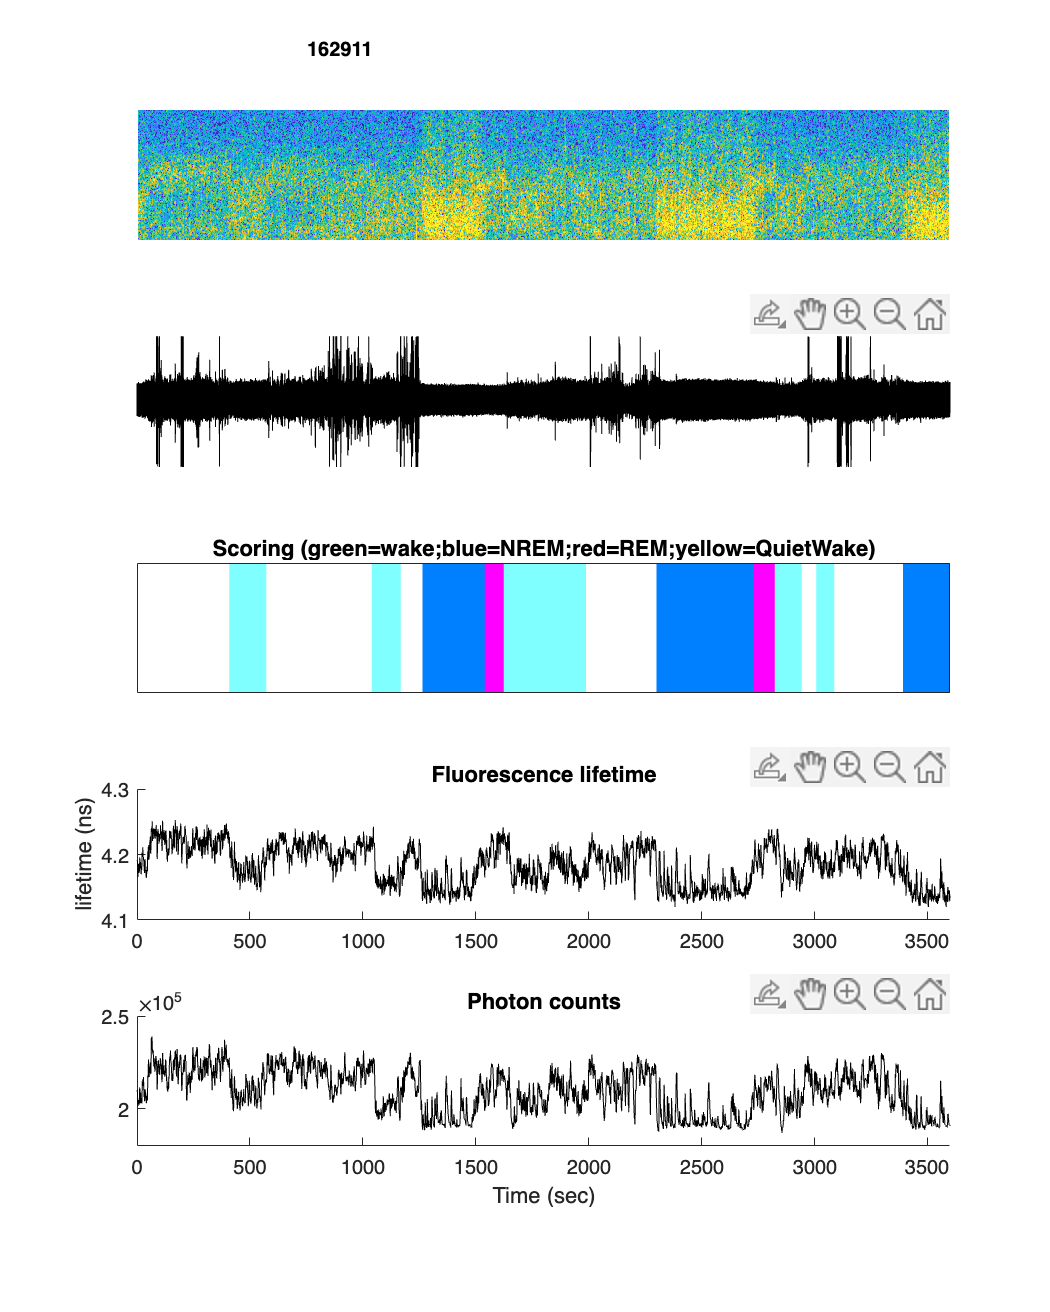



subplot4 = subplot(5,1,4,'Parent',figure1);
hold(subplot4,'on');

% Create plot
plot(time,tau_empTrunc,'Color', 'k','Parent', subplot4); % Pingchuan changed from tau to tau_empTrunc, based my FLiP analysis output, I can choose which tau to plot.
% scatter(time(1973:3430),tau(1973:3430), 10, 'filled','b');
xlim(subplot4,[0 3600]);
ylim(subplot4,[4.1 4.3]);

% Create ylabel
ylabel('lifetime (ns)');

% Create xlabel
xlabel(' ');

% Create title
title({'Fluorescence lifetime'});

% Uncomment the following line to preserve the Y-limits of the axes
% ylim(subplot4,[1.77 1.81]);
box(subplot4,'off');
% axis(subplot4,'off');
hold(subplot4,'off');

subplot5 = subplot(5,1,5,'Parent',figure1);
hold(subplot5,'on');

% Create plot
plot(time,photoncount,'Color','k','Parent', subplot5);
xlim(subplot5,[0 3600]);
ylim(subplot5,[180000 250000]);

% Create xlabel
xlabel('Time (sec)');

% Create title
title('Photon counts');


% Uncomment the following line to preserve the Y-limits of the axes
% ylim(subplot5,[190000 240000]);
box(subplot5,'off');
% axis(subplot5, 'off')
hold(subplot5,'off');
% Create textbox
OverallTitle=[mouse, num2str(acqn)];
annotation(figure1,'textbox',...
    [0.282608695652174 0.94695127409373 0.386287614404159 0.0299003316648511],...
    'String',OverallTitle,...
    'LineStyle','none',...
    'FontWeight','bold');

% Insert title for the whole figure;

% savefig(figure1,'acq26_for_plot.fig')

range(photoncount)

ans = 51961

range(tau_empTrunc)

ans = 0.1329

range(ScaledEEGEMG{3,1})

ans = 798.7467